clear all; close all; clc

% Create path
fold = fileparts(which('example_live.mlx'))

fold = 'C:\Users\Tim\Documents\GitHub\ultrasound-automated-algorithm'

cd(fold); % set cd to that folder
addpath(genpath(cd)); % add all subfolders of cd to path


## Step 0: Load and plot image

data must be an NxMx3 uint8

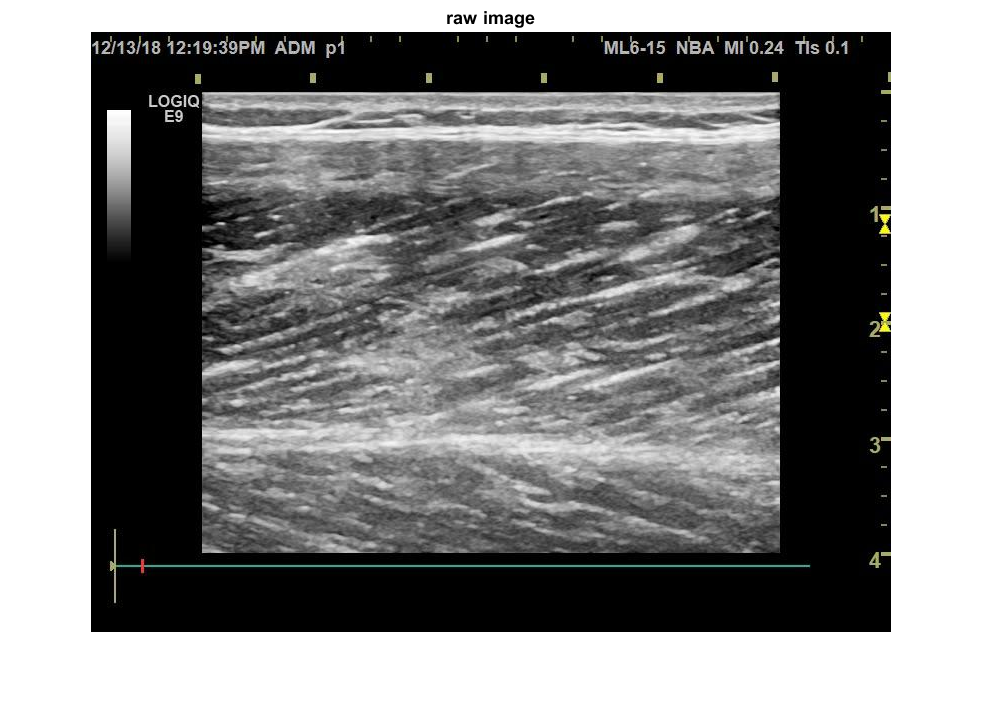

load('parms.mat'); % start with default parameters
load('example_ultrasound_image.mat'); % example image
pixtocm = (522-61)/4; % pixel to centimeter ratio (scale on image)
[n,m,p] = size(data); % nxmx3

figure;
imshow(data); title('raw image')

## Step 1: Frangi filtering

% aponeurosis filtering
parms.apo.frangi.BlackWhite = false; % DO NOT check this box unless you want to detect black objects instead of white ones
parms.apo.frangi.FrangiScaleRange(1) = 8; % lower limit on thickness range (pixels)
parms.apo.frangi.FrangiScaleRange(2) = 14; % upper limit on thickness range (pixels)
aponeurosis = FrangiFilter2D(double(rgb2gray(data)), parms.apo.frangi);

Current Frangi Filter Sigma: 8
Current Frangi Filter Sigma: 10
Current Frangi Filter Sigma: 12
Current Frangi Filter Sigma: 14


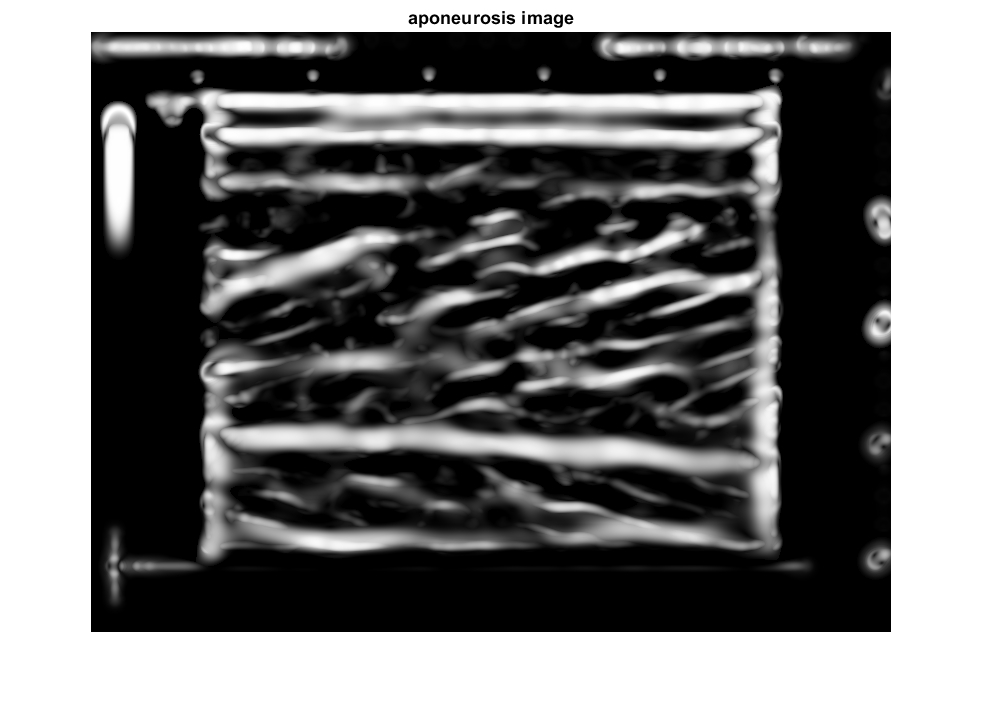

figure; imshow(aponeurosis); title('aponeurosis image')


% fascicle filtering
parms.fas.frangi.BlackWhite = false; % DO NOT check this box unless you want to detect black objects instead of white ones
parms.fas.frangi.FrangiScaleRange(1) = 1; % lower limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRange(2) = 3; % upper limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRatio = 1 % step size within specified range (default = 2)

parms = struct with fields:
    frangi: [1×1 struct]
       fas: [1×1 struct]
       apo: [1×1 struct]


fascicle = FrangiFilter2D(double(rgb2gray(data)), parms.fas.frangi);

Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2
Current Frangi Filter Sigma: 3


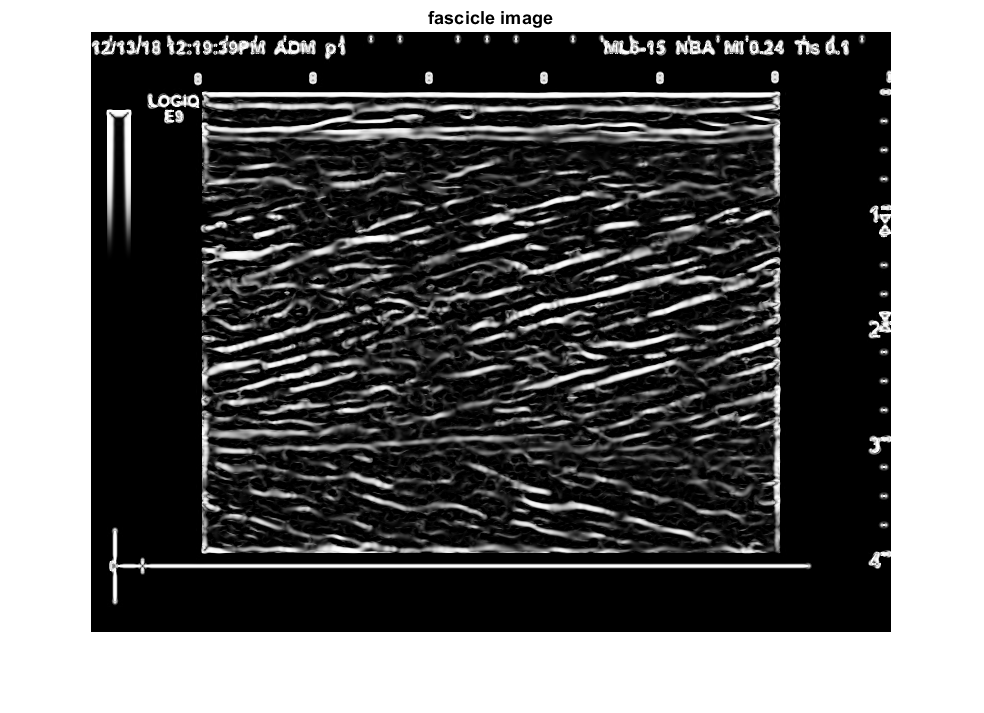

figure; imshow(fascicle); title('fascicle image')

## Step 2a: Aponeurosis detection

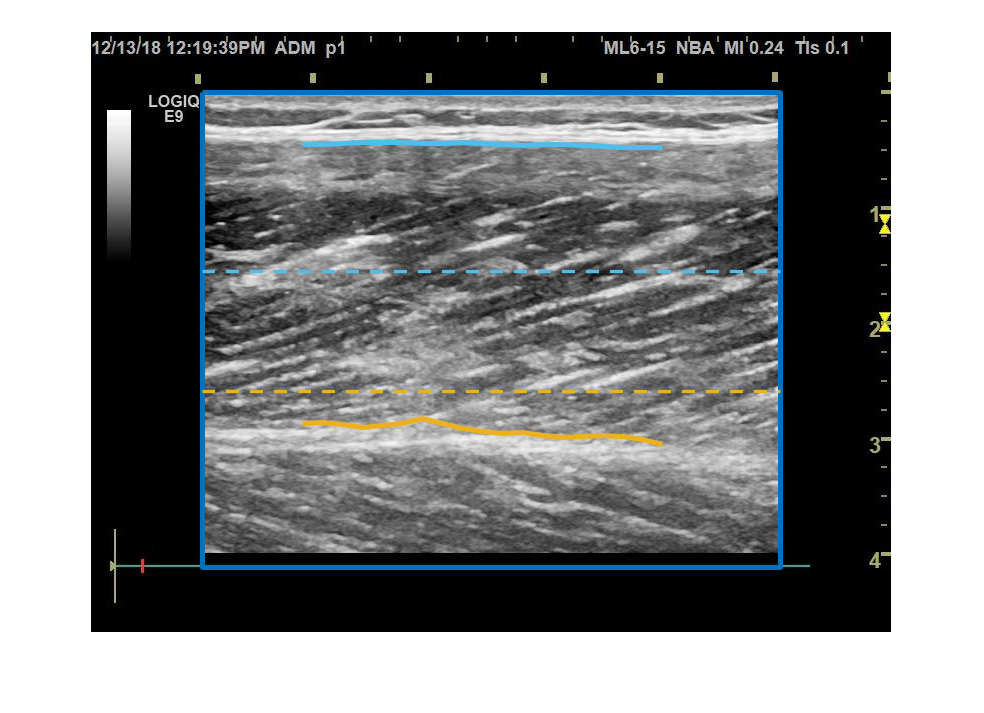

% Parameters
parms.apo.cut = 0.4;
parms.apo.superrange(1) = -30; % smallest superficial aponeurosis angle considered (deg)
parms.apo.superrange(2) = 10; % largest superficial aponeurosis considered (deg)
parms.apo.deeprange(1) = -20; % smallest superficial aponeurosis angle considered (deg)
parms.apo.deeprange(2) = 10; % largest superficial aponeurosis considered (deg)
parms.apo.margin = 100; % distance between start aponeurosis objects and the sides (pixels)
parms.apo.spacing = 20; % horizontal spacing for aponeurosis (pixels) 
parms.apo.minlength = 200; % minimal length for aponeurosis object (pixels) 
parms.apo.maxlengthratio = 0.8; % maximal ratio between length along first and second principle axes 

% Cutting the muscle pixels out of the total image
[aponeurosis_cutted, vert, hori] = cut_apo(data, aponeurosis);
parms.apo.apox = (vert(1)+parms.apo.margin):parms.apo.spacing:(vert(2)-parms.apo.margin);
n_apo = length(parms.apo.apox);
c = parms.apo.cut;

% Plot regions (dashed thin lines)
figure; color = get(gca,'colororder'); imshow(data); hold on; 
plot([vert(1) vert(2) vert(2) vert(1) vert(1)],[hori(1) hori(1) hori(2) hori(2) hori(1)], 'linewidth',3,'color',color(1,:)); % image region
plot([vert(1) vert(2)], [n*(1-c) n*(1-c)], '--','linewidth', 2,'color', color(3,:))
plot([vert(1) vert(2)], [n*c n*c], '--','linewidth', 2, 'color', color(6,:))

% Find aponeurosis
deep_aponeurosis = deepapo_func(aponeurosis_cutted, parms.apo);
super_aponeurosis = superapo_func(aponeurosis_cutted, parms.apo);

% Plot objects (thick solid lines)
plot(parms.apo.apox, deep_aponeurosis, 'linewidth',3, 'color', color(3,:))
plot(parms.apo.apox, super_aponeurosis, 'linewidth',3, 'color', color(6,:)); 


% Determine superficial aponeurosis angle
thickness = (mean(deep_aponeurosis-super_aponeurosis,'omitnan')) / pixtocm;
dx = parms.apo.apox(end) - parms.apo.apox(round(n_apo/2));
dy = super_aponeurosis(:,round(n_apo/2)) - super_aponeurosis(:,end); % negative if downward
betha = atan2d(dy,dx);  

if sum(isnan(deep_aponeurosis)) == length(deep_aponeurosis)
    disp('Not able to find a deep aponeurosis, try changing the parameters')
end

if sum(isnan(super_aponeurosis)) == length(super_aponeurosis)
    disp('Not able to find a superficial aponeurosis, try changing the parameters')
end

% Show superficial aponeurosis angle and muscle thickness
disp(['Superficial aponeurosis angle = ' , num2str(round(betha,3)), ' deg' ])

Superficial aponeurosis angle = -1.273 deg


disp(['Muscle thickness = ' , num2str(round(thickness,3)), ' cm' ])

Muscle thickness = 2.482 cm


## Step 2b: Fascicle detection

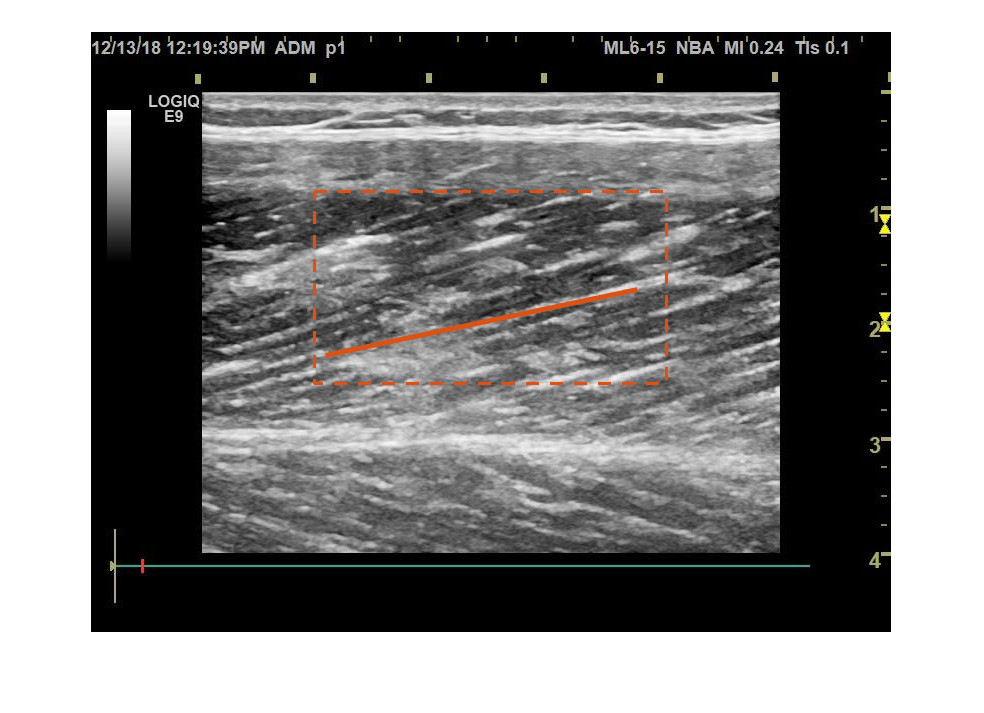

parms.fas.middle = round((mean(deep_aponeurosis) + mean(super_aponeurosis))/2);
parms.fas.cut(1) = 0.16; % relative amount kept from the middle
parms.fas.cut(2) = 0.28; % relative amount cut on the sides
parms.fas.npeaks = 10; % amount of Hough angles included in weighted average
parms.fas.range(1) = 10; % smallest pennation angle considered (deg)
parms.fas.range(2) = 30; % largest pennation angle considered (deg)
parms.fas.range = parms.fas.range + round(betha); % take superficial aponeurosis angle into account
c = parms.fas.cut;
    
figure; imshow(data); hold on
plot([m*c(2) m*(1-c(2)) m*(1-c(2)) m*c(2) m*c(2)], [parms.fas.middle-(n*c(1)), parms.fas.middle-(n*c(1)) parms.fas.middle+(n*c(1)) parms.fas.middle+(n*c(1)) parms.fas.middle-(n*c(1))] ,'--', 'linewidth', 2, 'color', color(2,:))
[alpha, fascicle_lines] = dohough(fascicle,parms.fas);
plot([fascicle_lines(1,1) fascicle_lines(1,3)],[fascicle_lines(1,2) fascicle_lines(1,4)],'LineWidth',3, 'color', color(2,:))


% Show fascicle angle
disp(['Fascicle angle = ' , num2str(round(alpha,3)), ' deg' ])

Fascicle angle = 14.415 deg


## Step 3: Fascicle length calculation

% Pennation angle (phi) and fascicle length
phi = alpha - betha;
faslen = thickness ./ sind(phi);

% Show pennation angle and fascicle length
disp(['Pennation angle = ' , num2str(round(phi,2)), ' deg' ])

Pennation angle = 15.69 deg


disp(['Fascicle length = ' , num2str(round(faslen,2)), ' cm'])

Fascicle length = 9.18 cm



% save parameters for next use
cd(fold)
save('parms.mat','parms')